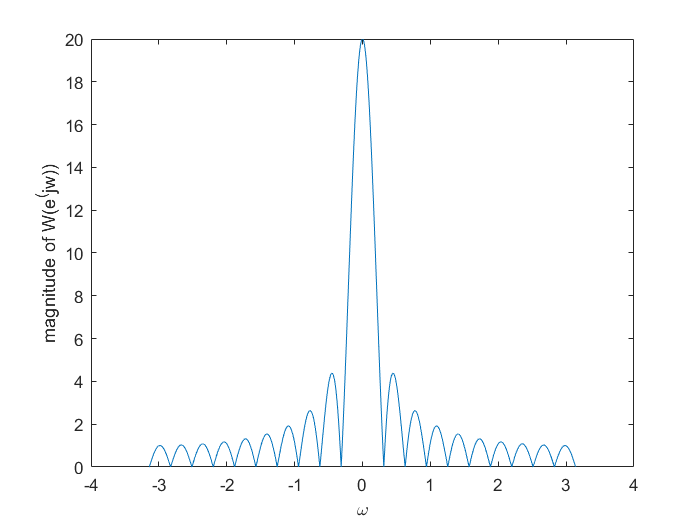

%4.2.3.1
N=20;
omega=-pi:pi/500:pi;
if rem(omega,2*pi) == 0
    W=N;
else
    W=exp(-1i*omega*(N-1)/2).*sin(omega*N/2)./sin(omega/2);
end
plot(omega,abs(W));
xlabel('\omega');
ylabel('magnitude of W(e^(jw))');

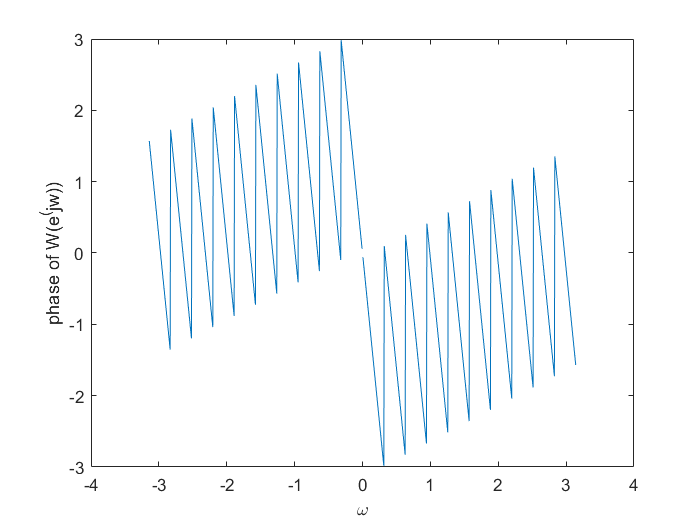

plot(omega,angle(W));
xlabel('\omega');
ylabel('phase of W(e^(jw))');

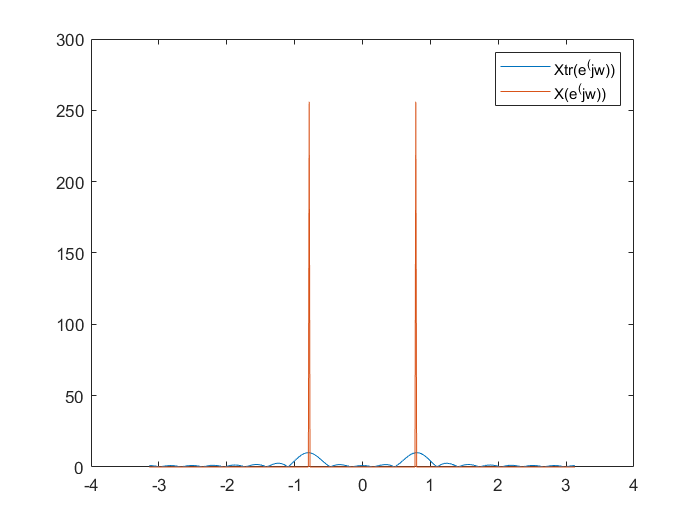


%4.2.3.3
l=512;
n=0:l-1;
x=cos(pi/4*n);
w=[ones(1,20) zeros(1,512-20)];
xtr=x.*w;
[X,wx]=DTFT(x,512);
[Xtr,wXtr]=DTFT(xtr,512);
plot(wXtr,abs(Xtr));hold on
plot(wx,abs(X));
legend('Xtr(e^(jw))','X(e^(jw))')

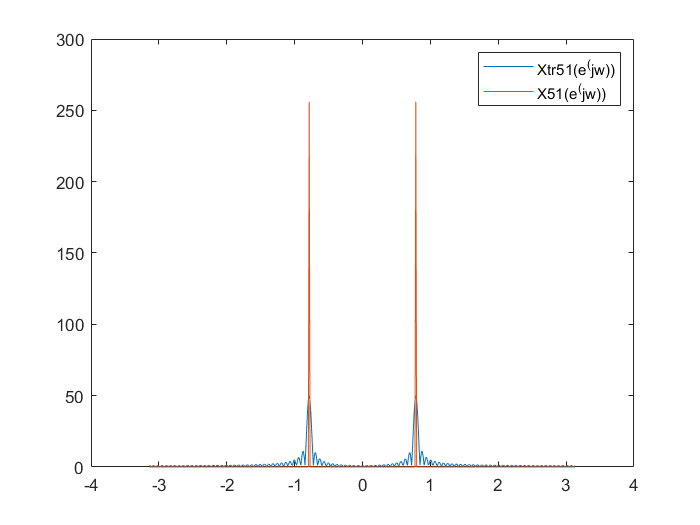


%5
N51=100;
w51=[ones(1,N51) zeros(1,512-N51)];
xtr51=x.*w51;
[X51,wx51]=DTFT(x,512);
[Xtr51,wXtr51]=DTFT(xtr51,512);
figure;
plot(wXtr51,abs(Xtr51));hold on
plot(wx51,abs(X51));
legend('Xtr51(e^(jw))','X51(e^(jw))')

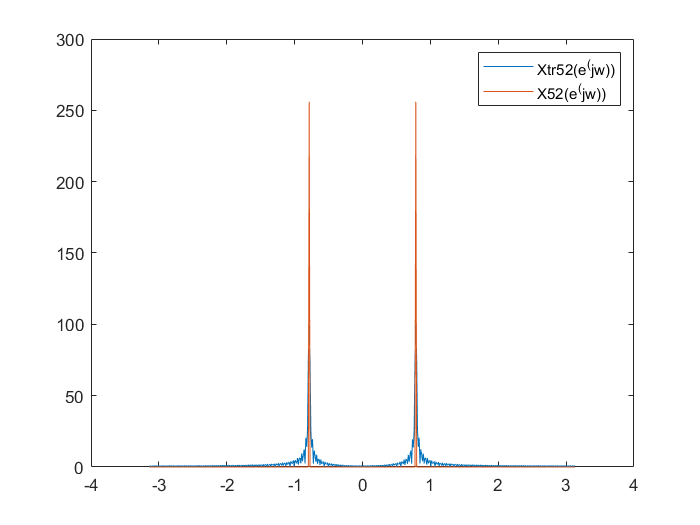


N52=200;
w52=[ones(1,N52) zeros(1,512-N52)];
xtr52=x.*w52;
[X52,wx52]=DTFT(x,512);
[Xtr52,wXtr52]=DTFT(xtr52,512);
figure;
plot(wXtr52,abs(Xtr52));hold on
plot(wx52,abs(X52));
legend('Xtr52(e^(jw))','X52(e^(jw))')